mask = zeros(16,16);
for n = 1:size(mask,1)
    for m = 1:size(mask,2)
        mask(n,m) = manhat(n,m,9,9);
    end
end
mask

mask =     16    15    14    13    12    11    10     9     8     9    10    11    12    13    14    15
    15    14    13    12    11    10     9     8     7     8     9    10    11    12    13    14
    14    13    12    11    10     9     8     7     6     7     8     9    10    11    12    13
    13    12    11    10     9     8     7     6     5     6     7     8     9    10    11    12
    12    11    10     9     8     7     6     5     4     5     6     7     8     9    10    11
    11    10     9     8     7     6     5     4     3     4     5     6     7     8     9    10
    10     9     8     7     6     5     4     3     2     3     4     5     6     7     8     9
     9     8     7     6     5     4     3     2     1     2     3     4     5     6     7     8
     8     7     6     5     4     3     2     1     0     1     2     3     4     5     6     7
     9     8     7     6     5     4     3     2     1     2     3     4     5     6     7     8


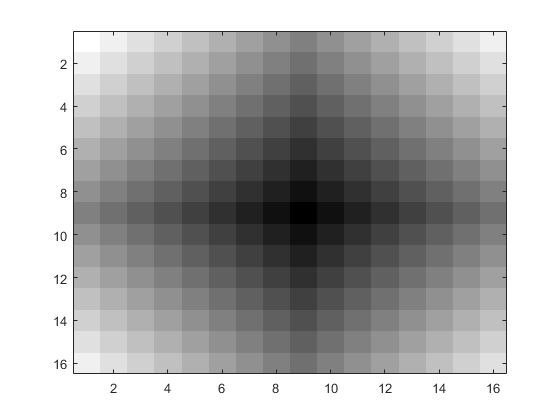


axis image;
colormap('gray');
%figure
imagesc(mask);

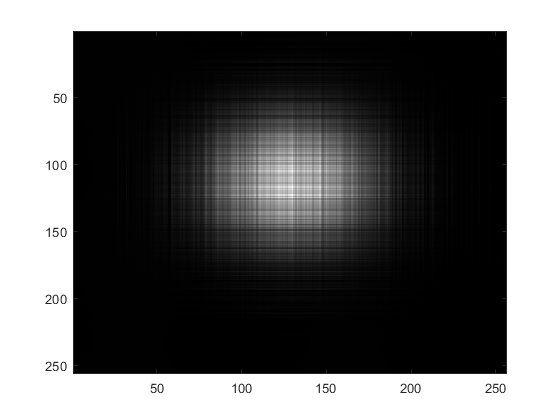


k = 10;
M = eye(16);
M = M.*(mask<=k);


load('waves.mat');
ftwaves = fft2(waves);
imagesc(waves);

abs(ftwaves)

ans = 	1.0e+06 *

    1.2422    0.8677    0.3382    0.0623    0.0029    0.0074    0.0143    0.0111    0.0186    0.0139    0.0004    0.0044    0.0024    0.0075    0.0070    0.0038    0.0075    0.0143    0.0126    0.0061    0.0024    0.0041    0.0117    0.0114    0.0038    0.0046    0.0073    0.0085    0.0119    0.0148    0.0126    0.0160    0.0106    0.0040    0.0092    0.0206    0.0237    0.0157    0.0109    0.0112    0.0066    0.0054    0.0092    0.0089    0.0048    0.0154    0.0116    0.0052    0.0110    0.0042
    0.8792    0.6443    0.2502    0.0462    0.0022    0.0055    0.0106    0.0082    0.0138    0.0104    0.0003    0.0033    0.0018    0.0056    0.0052    0.0028    0.0056    0.0106    0.0094    0.0045    0.0018    0.0030    0.0087    0.0084    0.0028    0.0035    0.0054    0.0063    0.0088    0.0110    0.0094    0.0119    0.0079    0.0030    0.0068    0.0153    0.0176    0.0116    0.0081    0.0083    0.0049    0.0040    0.0068    0.0066    0.0035    0.0114    0.0086    0.0038 

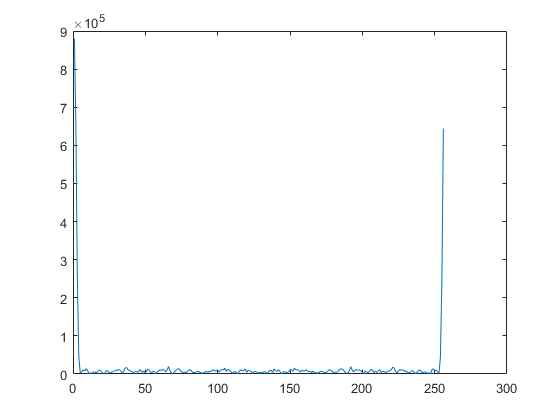

plot(abs(ftwaves(2,:)));

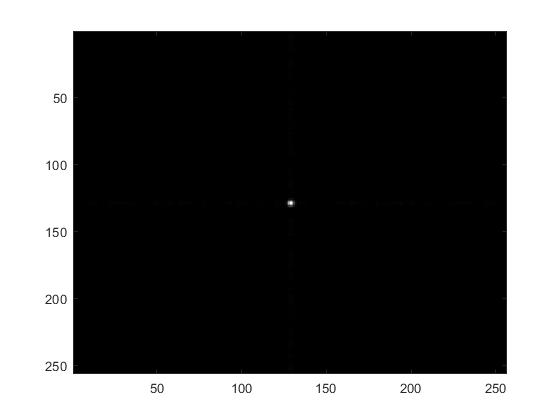

imagesc(fftshift(abs(ftwaves)))

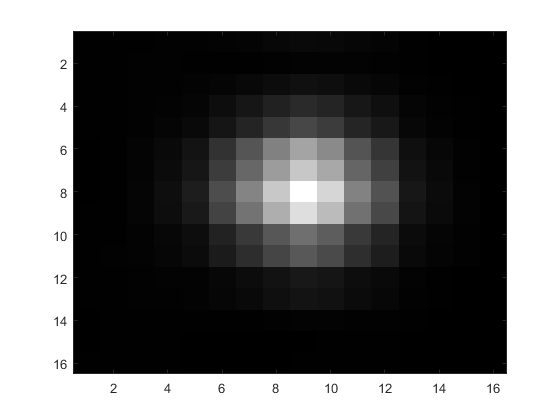



% Skapa shortwaves
shortwaves = waves(1:16:256,1:16:256);

% Upprepa för shortwaves
ftshortwaves = fft2(shortwaves);
imagesc(shortwaves);

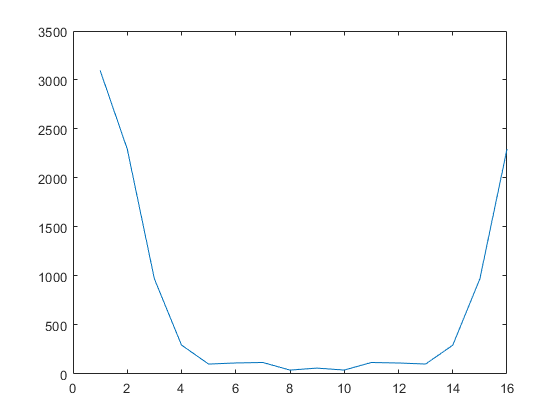

abs(ftshortwaves);
plot(abs(ftshortwaves(2,:)))

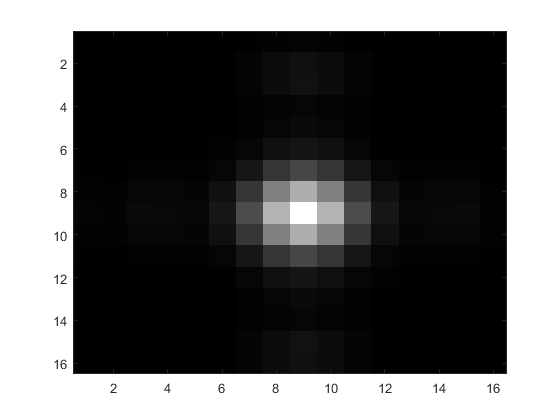

imagesc(fftshift(abs(ftshortwaves)))


imagesc(ifft2(fftshift(fftshift(fft2(shortwaves)))))

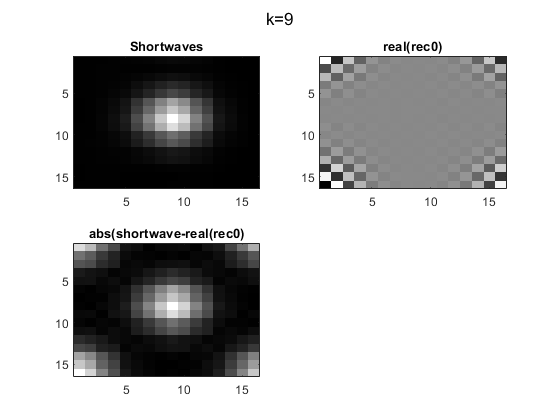

for k = 0:9
    ftshortwaves0 = fftshift((ftshortwaves));
    % a)
    ftshortwaves0 = ftshortwaves0.*(mask<=k);
    
    % b)
    rec0 = fftshift(ifft2(ftshortwaves0));
    
    % c)
    %imagesc(real(rec0))
    %imagesc(abs(rec0))
    
    % d)
    subplot(2,2,1);
    imagesc(shortwaves)
    title('Shortwaves')
    subplot(2,2,2)
    imagesc(real(rec0))
    title('real(rec0)')
    subplot(2,2,3);
    imagesc(abs(shortwaves-real(rec0)))
    title('abs(shortwave-real(rec0)')
    sgtitle(['k=',num2str(k)]);
    pause
end